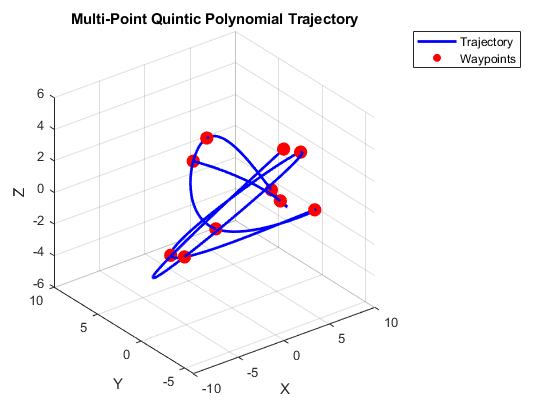

clc, clear;
% Define your waypoints (modify as needed)
waypoints = [-2.5, 1.8, 3.2;   % Waypoint 1
             0.7, -4.9, 2.3;   % Waypoint 2
             6.4, 2.1, -0.6;
             -3.2, -0.5, 5.6;
             1.9, 3.8, -2.7;
             4.2, -5.2, 1.1;
             -0.3, 6.7, -4.9;
             5.6, -2.1, 3.4;
             -4.8, 0.4, -1.9;
             2.3, -3.6, 4.8];

% Specify start and end times for the trajectory
timeInterval = [0, 1];  % Adjust as needed

% Create a time vector for sampling the trajectory
timeSamples = linspace(timeInterval(1), timeInterval(2), 1000);  % Adjust the number of samples

% Generate the multi-point quintic polynomial trajectory
[positions, velocities, accelerations] = generateQuinticPolynomialTrajectory(waypoints, timeSamples);

% Plot the trajectory and waypoints
figure;
plot3(positions(:,1), positions(:,2), positions(:,3), '-b', 'LineWidth', 2);
hold on;
scatter3(waypoints(:,1), waypoints(:,2), waypoints(:,3), 100, 'ro', 'filled');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Multi-Point Quintic Polynomial Trajectory');
legend('Trajectory', 'Waypoints');
grid on;
hold off;


% Display peak velocity and acceleration
maxVelocity = max(vecnorm(velocities));
maxAcceleration = max(vecnorm(accelerations));
fprintf('Peak Velocity: %.2f m/s\n', maxVelocity);

Peak Velocity: 2472.50 m/s


fprintf('Peak Acceleration: %.2f m/s^2\n', maxAcceleration);

Peak Acceleration: 63418.58 m/s^2



% Function to generate quintic polynomial trajectory

function [positions, velocities, accelerations] = generateQuinticPolynomialTrajectory(waypoints, timeSamples)
    t = linspace(0, 1, size(waypoints, 1));
    pp = spline(t, waypoints');
    positions = ppval(pp, timeSamples)';
    velocities = ppval(fnder(pp, 1), timeSamples)';
    accelerations = ppval(fnder(pp, 2), timeSamples)';
end
